# Quantifying muscle activity and response latency

## Load data

fid = fopen('20210121-Axillary-M4-T2-rec.txt', 'r');
data = fscanf(fid,'%f');
% Load stimulus data 

stimulus = data(70001:140000)/10;  %stimulus feedback % Correct the gain of the stimulus
response = data(1:70000);  % muscle response 
samplingRate = 10000;
response = response - response(1); 
dataLength = length(stimulus);


## Bandpass filter

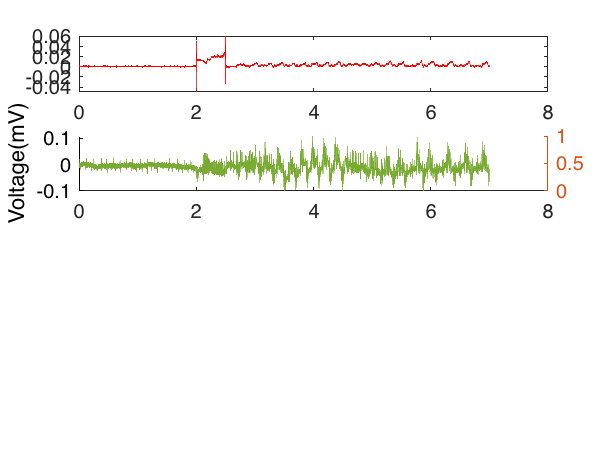

Unrecognized function or variable 'filteredData1'.

lowCut = 50;
highCut = 1000;
order =3;
[A,B,C,D] = butter(order,[lowCut highCut]/(samplingRate/2)); 
t=0:1/samplingRate:(length(response)/samplingRate);
t(end)=[];
[sos,g] = ss2sos(A,B,C,D);
filteredData = filtfilt(sos,g,response);

figure;
subplot(4,1,1);
plot(t, stimulus, 'color', 'r')


subplot(4,1,2);
hold on; plot(t,response, 'color',[0.4660 0.6740 0.1880]);
ylabel ('Voltage(mV)'); % Skip dividing the data by 1000 if you are using mV as unit. 
yyaxis right; plot(t,filteredData1, '-b'); hold on;

title('Bandpass filtered data');
xlabel ('Time (sec)'); ylabel ('Voltage(mV)');
legend('raw data','filteredData')

subplot(4,1,3);
hold on; plot(t,response2, 'color',[0.4660 0.6740 0.1880]);
ylabel ('Voltage(mV)'); % Skip dividing the data by 1000 if you are using mV as unit. 
yyaxis right; plot(t,filteredData2, '-b'); hold on;
title('Bandpass filtered data');
xlabel ('Time (sec)'); ylabel ('Voltage(mV)');
legend('raw data','filteredData')

subplot(4,1,4);
hold on; plot(t,response3, 'color',[0.4660 0.6740 0.1880]);
ylabel ('Voltage(mV)'); % Skip dividing the data by 1000 if you are using mV as unit. 
yyaxis right; plot(t,filteredData3, '-b'); hold on;
title('Bandpass filtered data');

xlabel ('Time (sec)'); ylabel ('Voltage(mV)');
legend('raw data','filteredData')


## Finding spikes

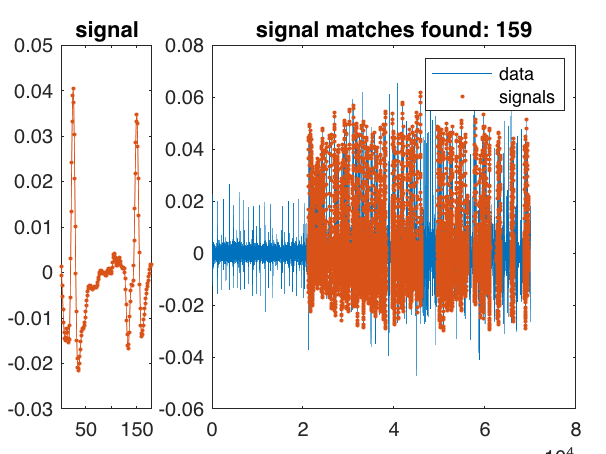

%Templates
%Axillary
% spikeType1 = filteredData(1060:1110);%M2_T1
% spikeType2 = filteredData(21946:21991);
% spikeType3 = filteredData(21374:21410);
% spikeType1 = filteredData(11174:11209);%M2_T2
% spikeType2 = filteredData(23531:23587);
% spikeType3 = filteredData(22545:22564);
% spikeType1 = filteredData(04385:04420);%M2_T3
% spikeType2= filteredData(21268:21297);
% spikeType3= filteredData(2346:2412);
% spikeType1 = filteredData(3304:3378);%M3_T1
% spikeType2 = filteredData(21420:21462);
% spikeType3= filteredData(25811:25841);
% spikeType1 = filteredData(9464:9553)%M3_T2
% spikeType2 = filteredData(28075:28110)
spikeType1 = filteredData(36021:36200);%M3_T3
spikeType2 = filteredData(26176:26216);
spikeType3= filteredData(25357:25380);
% spikeType1 = filteredData(11250:11351);%M6_T1
% spikeType2 = filteredData(05242:05265);
% spikeType3= filteredData(28005:28039);
% spikeType1 = filteredData(6332:6424);%M6_T2
% spikeType2 = filteredData(21594:21698);
% spikeType3= filteredData(39350:39392);
% spikeType1 = filteredData(3503:3584);%M6_T3
% spikeType2 = filteredData(28415:28443);
% spikeType3= filteredData(35208:35241);

%Basalar
% spikeType1 = filteredData(30344:30395);%M1_T1
% spikeType2 = filteredData(28906:28941);
% spikeType3 = filteredData(29356:29408);
% spikeType1 = filteredData(24122:24171);%M1_T2
% spikeType2 = filteredData(30344:30395);
% spikeType1 = filteredData(22692:22725);%M1_T3
% spikeType2 = filteredData(22260:22294);
% spikeType1 = filteredData(22348:22407);%M2_T1
% spikeType2 = filteredData(21323:21358);
% spikeType1 = filteredData(21065:21106);%M2_T2
% spikeType2 = filteredData(21323:21358);
% spikeType1 = filteredData(22717:22751);%M2_T3
% spikeType2 = filteredData(22227:22266);
% spikeType1 = filteredData(22228:22274);%M3_T1
% spikeType2 = filteredData(22717:22751);
% spikeType1 = filteredData(21828:21887);%M3_T2
% spikeType2 = filteredData(22462:22501);
% spikeType1 = filteredData(21002:21046);%M3_T3
% spikeType2 = filteredData(21378:21449);
% spikeType3 = filteredData(39533:39609);


% Finding distances with high threshold 
[~,~, dist1] = findsignal(filteredData, spikeType1, 'TimeAlignment','dtw',"MaxDistance",1, "Normalization","center"); 
[~,~, dist2] = findsignal(filteredData, spikeType2, 'TimeAlignment','dtw',"MaxDistance",1, "Normalization","center"); 
[~,~, dist3] = findsignal(filteredData, spikeType2, 'TimeAlignment','dtw',"MaxDistance",1, "Normalization","center");

% percentile of distances
percentile = 50;
distSpType1 = prctile(dist1,percentile);
distSpType2 = prctile(dist2,percentile);
distSpType3 = prctile(dist3,percentile);

% Plotting for visualization
%figure;
findsignal(filteredData, spikeType1, 'TimeAlignment','dtw',"MaxDistance", distSpType1, "Normalization","center"); 

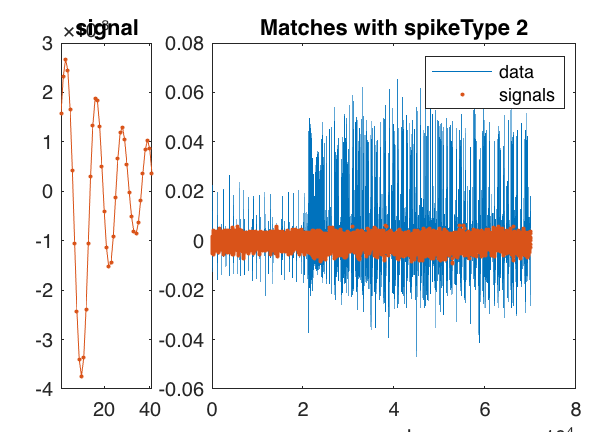

%xlabel('samples');
% % title('Matches with 75 percentile max distance, spikeType 1');
%title('Matches with spikeType 1');

figure;
findsignal(filteredData, spikeType2, 'TimeAlignment','dtw',"MaxDistance", distSpType2, "Normalization","center"); 
% title('Matches with 75 percentile max distance, spikeType 2');
title('Matches with spikeType 2');
xlabel('samples');

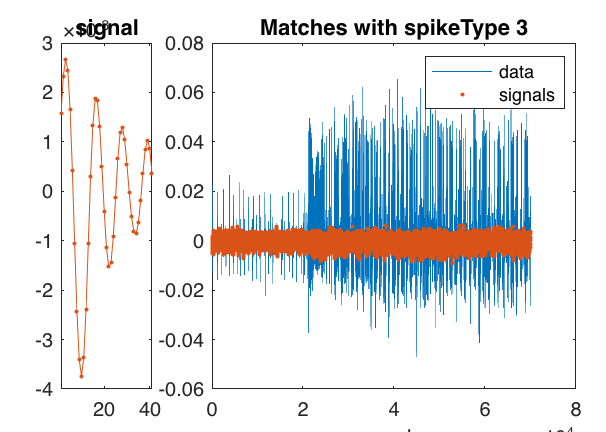


figure;
findsignal(filteredData, spikeType2, 'TimeAlignment','dtw',"MaxDistance", distSpType3, "Normalization","center");
% title('Matches with 75 percentile max distance, spikeType 3');
title('Matches with spikeType 3');
xlabel('samples');


% Getting start and stop points for matched signals with MaxDistance at specified percentile above

spStart1 = []; spStop1 = [];
spStart2 = []; spStop2 = [];
spStart3 = []; spStop3 = [];
d1=[]; d2=[]; d3= [];
% [spStart1,spStop1, d1] = findsignal(filteredData, spikeType1, 'TimeAlignment','dtw',"MaxDistance",distSpType1, "Normalization","center"); 
[spStart2,spStop2, d2] = findsignal(filteredData, spikeType2, 'TimeAlignment','dtw',"MaxDistance",distSpType2, "Normalization","center"); 
[spStart3,spStop3, d3] = findsignal(filteredData, spikeType3, 'TimeAlignment','dtw',"MaxDistance",distSpType3, "Normalization","center"); 
pts=[spStart1 spStop1; spStart2 spStop2; spStart3 spStop3];
distances = [d1; d2; d3];

spStart = sort(pts(:,1),'ascend');
spStop = sort(pts(:,2),'ascend');


## Eliminating false positives and visualizing

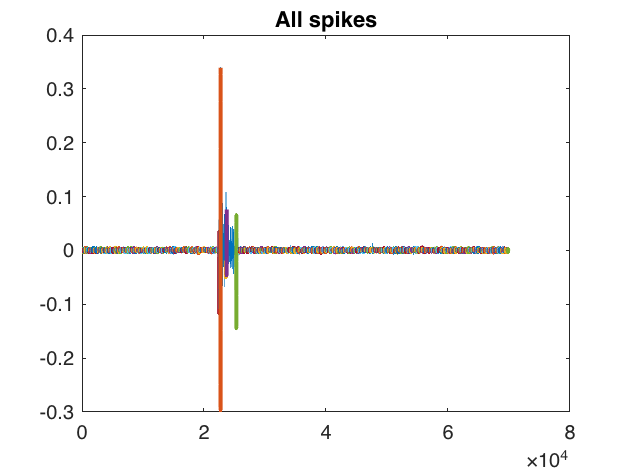

% % Visualising start and stop points of matched signals
% figure;
% plot(filteredData); hold on;
% plot(spStop, filteredData(spStop), 'k.', 'MarkerSize',10);
% plot(spStart, filteredData(spStart), 'r.','MarkerSize',10);
% legend('filtered data', 'spike stop', 'spike start', 'Location',"best");

% spStop = [1; spStop];
spikes = []; %nan(length(spStop), length(spikeType1));
range = [];
peaks = [];

for i=1:length(spStart)
    spikes(i,:) = filteredData(spStart(i) : spStart(i)+length(spikeType1)-1);
    range(i) = max(spikes(i,:)) - min(spikes(i,:)); 
    peaks(i) = max(spikes(i,:));
end

% Visualizing all spikes
figure;
plot(filteredData); hold on;
title('All spikes')
for i=1:length(spStart)
    plot(spStart(i):spStart(i)+size(spikes,2)-1, spikes(i,:), 'LineWidth', 2); hold on;
end

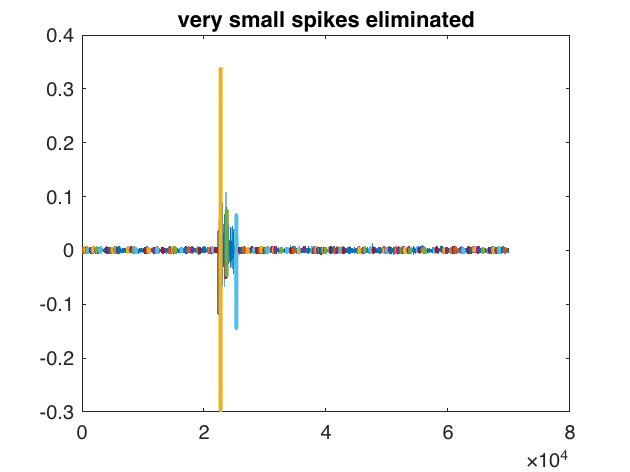


% Eliminating matched signals that have very small amplitude
smallSignalThresh = prctile(range, 75);
ignoreSpikesIdx = find(range < smallSignalThresh);

spikes(ignoreSpikesIdx, :) = [];
range(ignoreSpikesIdx) = [];
spStart(ignoreSpikesIdx) = [];
spStop(ignoreSpikesIdx) = [];

% Visualizing remaining spikes
figure;
plot(filteredData); hold on;
title('very small spikes eliminated')
for i=1:length(spStart)
    plot(spStart(i):spStart(i)+size(spikes,2)-1, spikes(i,:), 'LineWidth', 2); hold on;
end

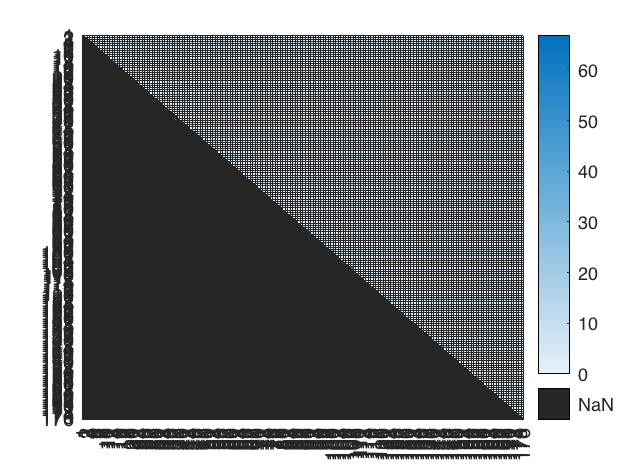


% Eliminating redundant matches 
overlaps = nan(length(spStart),length(spStart));
redundantIdx = [];

for i = 1:length(spStart)
    for j = i+1:length(spStart)
        intersectSegment = intersect(spStart(i):spStop(i), spStart(j):spStop(j));
        totalRange = min([spStart(i), spStart(j)]) : max([spStop(i), spStop(j)]);
        overlaps(i,j) = length(intersectSegment)*100/length(totalRange);

        if overlaps(i,j) > 5

            %Retains the signal with shorted matcching distance
            % if distances(i) <= distances(j)
            %     redundantIdx = [redundantIdx j];
            % else
            %     redundantIdx = [redundantIdx i];
            % end

            % Retains the matched signal that has the larger peak value
            if max(filteredData(spStart(i):spStop(i))) >= max(filteredData(spStart(j):spStop(j)))
                redundantIdx = [redundantIdx j];
            else
                redundantIdx = [redundantIdx i];
            end
        end
    end
end

figure;
heatmap(overlaps);

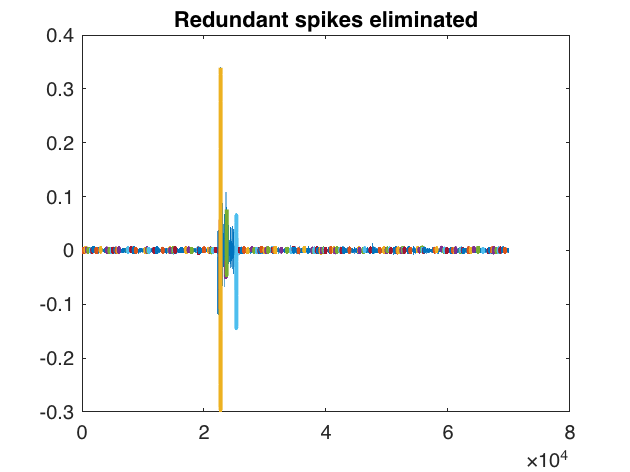



% closeStartIdx = find(diff(spStart)<20) +1 % Start points closer than 1 ms
spikes(redundantIdx, :) = [];
range(redundantIdx) = [];
spStart(redundantIdx) = [];
spStop(redundantIdx) = [];

% Visualizing remaining spikes
figure;
plot(filteredData); hold on;
title('Redundant spikes eliminated')
for i=1:length(spStart)
    plot(spStart(i):spStart(i)+size(spikes,2)-1, spikes(i,:), 'LineWidth', 2); hold on;
end

## Find spike times and raster plot

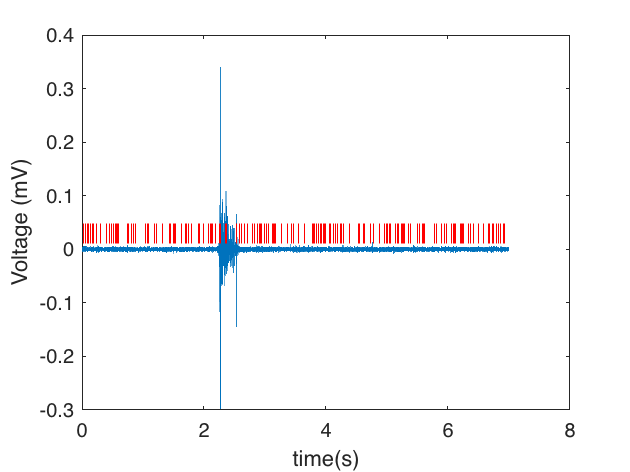

% Take the mid-point of peak and trough locations as spike time.
spLoc = [];
[~,spikePeakLoc] = max(spikes,[],2);
[~,spikeTroughLoc] = min(spikes,[],2);
for ispike = 1 : length(spStart)
    spLoc(ispike) = spStart(ispike) + min([spikePeakLoc(ispike) spikeTroughLoc(ispike)]) + round(0.5 * abs(spikePeakLoc(ispike) - spikeTroughLoc(ispike)));
end

figure;
plot(t,filteredData); hold on;
plot(spLoc/samplingRate,0.03*ones(1,length(spLoc)), 'r|', 'MarkerSize',10);
xlabel('time(s)');
ylabel('Voltage (mV)');

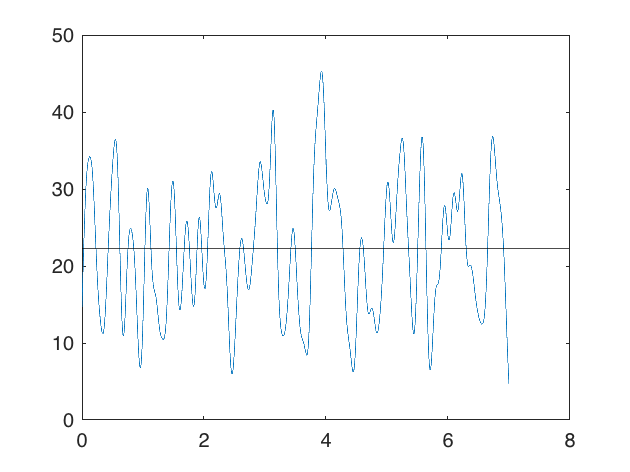


raster = zeros(1,length(filteredData));
raster(1,spLoc) = 1;

% Firing rate
gauss_win_L = 0.5 * samplingRate; %500 ms
gauss_win_sigma = 0.05 * samplingRate; % 50 ms
gauss_win_alpha = (gauss_win_L - 1)/(2*gauss_win_sigma);
gauss_window = gausswin(gauss_win_L, gauss_win_alpha);

gcfr = (samplingRate/sum(gauss_window))*conv(raster,gauss_window,'same');

baselineFR = gcfr(1:2*samplingRate);
meanBaselineFR = mean(baselineFR);
threshold = 3*std(baselineFR) ;

figure;
plot(t,gcfr); hold on;
yline(threshold, 'k');

## **Latency of muscle response**

[ymin, stimInd] = min(stimulus);
stimulusOnTime = t(stimInd)

stimulusOnTime = 2.0007

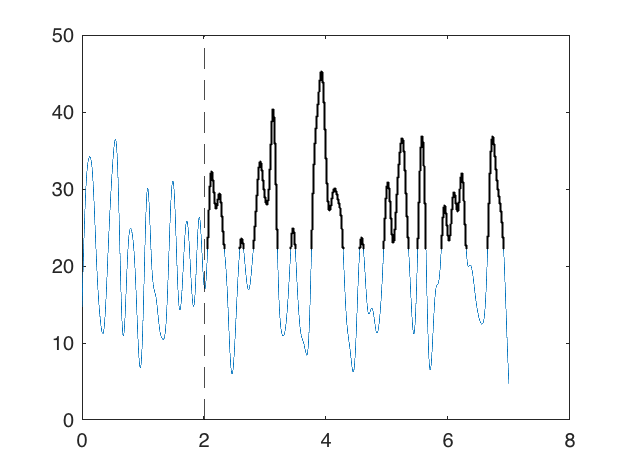



% Find where Amplitude first exceeds threshold:
locsAboveThresh = find(gcfr(2*samplingRate+1:end) > threshold);
locsAboveThresh = locsAboveThresh + 2*samplingRate;
figure; % You don't need this figure. But, you can visualise the algorithm.
plot(t, gcfr); hold on;
plot(locsAboveThresh/samplingRate, gcfr(locsAboveThresh), 'k.', 'MarkerSize',1); % marks all the points above threshold
xline(stimulusOnTime, 'k--');

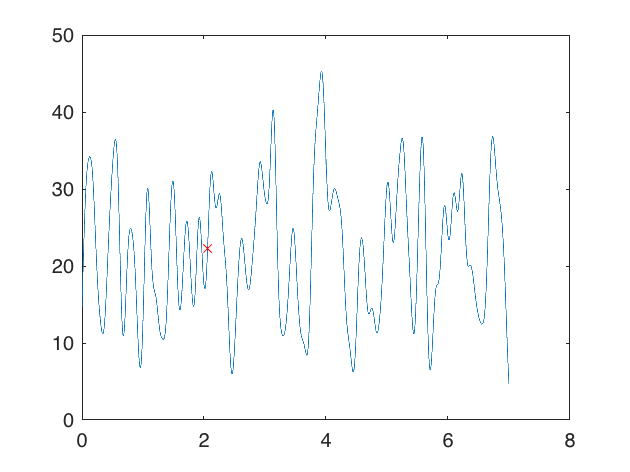

% Get time at that y value:
ind = find(locsAboveThresh > stimInd, 1,'first'); % Gets first index after stimulus
timeAtThresh = locsAboveThresh(ind)/samplingRate;
figure;
plot(t, gcfr); hold on;
plot(timeAtThresh, gcfr(locsAboveThresh(ind)), 'rx');

latency = ((timeAtThresh)-stimulusOnTime)*1000; 
disp(timeAtThresh);

    2.0588



disp(latency);

   58.1000

